%% Import data from spreadsheet
% Script for importing data from the following spreadsheet:
%
%    Workbook: C:\Daten\RU\Precision Machine Design\ANOVA\two_axis_test_sheet.ods
%    Worksheet: Tabelle1
%
% Auto-generated by MATLAB on 20-Nov-2024 20:02:47

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "Tabelle1";
opts.DataRange = "A5:G14";

% Specify column names and types
opts.VariableNames = ["Var1", "LoadingFromBottom", "VarName3", "LoadingFromTop", "VarName5", "Loading90InDragDirection", "VarName7"];
opts.SelectedVariableNames = ["LoadingFromBottom", "VarName3", "LoadingFromTop", "VarName5", "Loading90InDragDirection", "VarName7"];
opts.VariableTypes = ["char", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% Import the data
twoaxistestsheet = readtable("C:\Daten\RU\Precision Machine Design\ANOVA\two_axis_test_sheet.ods", opts, "UseExcel", true);

%% Convert to output type
sheet = table2array(twoaxistestsheet);

%% Clear temporary variables
clear opts


grams = cell(1,3)

grams = 1×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}



grams{1} = sheet(:,1)

grams = 1×3 cell array
    {10×1 double}    {0×0 double}    {0×0 double}


grams{2} = sheet(:,3)

grams = 1×3 cell array
    {10×1 double}    {10×1 double}    {0×0 double}


grams{3} = sheet(:,6)

grams = 1×3 cell array
    {10×1 double}    {10×1 double}    {10×1 double}


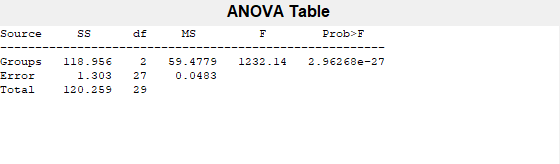

p_anova = 2.9627e-27

tbl = 4×6 cell array
    {'Source'}    {'SS'      }    {'df'}    {'MS'      }    {'F'         }    {'Prob>F'    }
    {'Groups'}    {[118.9558]}    {[ 2]}    {[ 59.4779]}    {[1.2321e+03]}    {[2.9627e-27]}
    {'Error' }    {[  1.3033]}    {[27]}    {[  0.0483]}    {0×0 double  }    {0×0 double  }
    {'Total' }    {[120.2591]}    {[29]}    {0×0 double}    {0×0 double  }    {0×0 double  }


stats = struct with fields:
    gnames: {3×1 cell}
         n: [10 10 10]
    source: 'anova1'
     means: [461.4050 461.4900 465.6710]
        df: 27
         s: 0.2197



% for k = 1:size(sheet,2)
%     grams{k} = sheet(:,k);
% end

% combine all data and group labels for ANOVA
data = cellfun(@(x) x(:), grams, 'UniformOutput', false);
group = arrayfun(@(x) repmat(x, size(grams{x}, 1), 1), 1:length(grams), 'UniformOutput', false);

% concatenate data and group for ANOVA
all_data = vertcat(data{:});
all_group = vertcat(group{:});

% perform one-way ANOVA
[p_anova, tbl, stats] = anova1(all_data, all_group)


% display the result
if p_anova < 0.05
    fprintf('Significant differences (p = %.4f)\n', p_anova);
else
    fprintf('No significant differences (p = %.4f)\n', p_anova);
end

Significant differences (p = 0.0000)


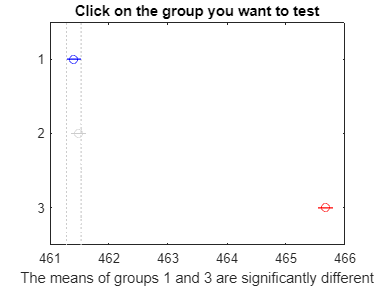

c =     1.0000    2.0000   -0.3286   -0.0850    0.1586    0.6665
    1.0000    3.0000   -4.5096   -4.2660   -4.0224         0
    2.0000    3.0000   -4.4246   -4.1810   -3.9374         0



% tukey's hsd test for significant differences
if p_anova < 0.05
    c = multcompare(stats)  % Post-hoc test to find specific group differences
end

grams_0 = cell(1,3)

grams_0 = 1×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}



grams_0{1} = sheet(:,2)

grams_0 = 1×3 cell array
    {10×1 double}    {0×0 double}    {0×0 double}


grams_0{2} = sheet(:,4)

grams_0 = 1×3 cell array
    {10×1 double}    {10×1 double}    {0×0 double}


grams_0{3} = sheet(:,5)

grams_0 = 1×3 cell array
    {10×1 double}    {10×1 double}    {10×1 double}


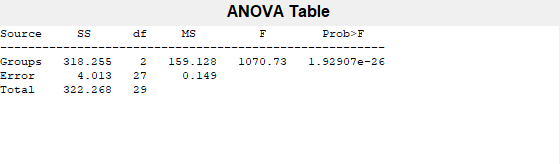

p_anova0 = 1.9291e-26

tbl0 = 4×6 cell array
    {'Source'}    {'SS'      }    {'df'}    {'MS'      }    {'F'         }    {'Prob>F'    }
    {'Groups'}    {[318.2553]}    {[ 2]}    {[159.1277]}    {[1.0707e+03]}    {[1.9291e-26]}
    {'Error' }    {[  4.0126]}    {[27]}    {[  0.1486]}    {0×0 double  }    {0×0 double  }
    {'Total' }    {[322.2679]}    {[29]}    {0×0 double}    {0×0 double  }    {0×0 double  }


stats0 = struct with fields:
    gnames: {3×1 cell}
         n: [10 10 10]
    source: 'anova1'
     means: [0.5240 6.6110 -0.8990]
        df: 27
         s: 0.3855



% for k = 1:size(sheet,2)
%     grams{k} = sheet(:,k);
% end

% combine all data and group labels for ANOVA
data0 = cellfun(@(x) x(:), grams_0, 'UniformOutput', false);
group0 = arrayfun(@(x) repmat(x, size(grams_0{x}, 1), 1), 1:length(grams_0), 'UniformOutput', false);

% concatenate data and group for ANOVA
all_data0 = vertcat(data0{:});
all_group0 = vertcat(group0{:});

figure()
% perform one-way ANOVA
[p_anova0, tbl0, stats0] = anova1(all_data0, all_group0)


% display the result
if p_anova0 < 0.05
    fprintf('Significant differences (p = %.4f)\n', p_anova);
else
    fprintf('No significant differences (p = %.4f)\n', p_anova);
end

Significant differences (p = 0.0000)


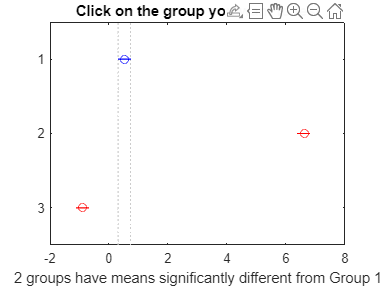

c =     1.0000    2.0000   -6.5145   -6.0870   -5.6595    0.0000
    1.0000    3.0000    0.9955    1.4230    1.8505    0.0000
    2.0000    3.0000    7.0825    7.5100    7.9375         0



% tukey's hsd test for significant differences
if p_anova0 < 0.05
    c = multcompare(stats0)  % Post-hoc test to find specific group differences
end